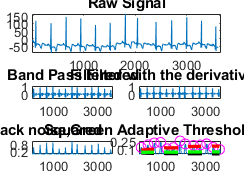

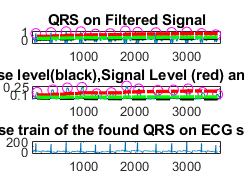

qrs_amp_raw =     0.6960    0.8127    0.9154    0.9121    0.6227    0.6928    1.0000    0.8492    0.7949    0.8246    0.8744    0.6959    0.5456


qrs_i_raw =           75         368         661         945        1229        1513        1808        2043        2400        2704        2996        3281        3557


delay = 30

load 100m.mat
[qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(val,400,1)

function [qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(ecg,fs,gr)
%% function [qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(ecg,fs)
% Complete implementation of Pan-Tompkins algorithm
%% Inputs
% ecg : raw ecg vector signal 1d signal
% fs : sampling frequency e.g. 200Hz, 400Hz and etc
% gr : flag to plot or not plot (set it 1 to have a plot or set it zero not
% to see any plots
%% Outputs
% qrs_amp_raw : amplitude of R waves amplitudes
% qrs_i_raw : index of R waves
% delay : number of samples which the signal is delayed due to the
% filtering
%% Method
% See Ref and supporting documents on researchgate.
% https://www.researchgate.net/publication/313673153_Matlab_Implementation_of_Pan_Tompkins_ECG_QRS_detector
%% References :
%[1] Sedghamiz. H, "Matlab Implementation of Pan Tompkins ECG QRS
%detector.",2014. (See researchgate)
%[2] PAN.J, TOMPKINS. W.J,"A Real-Time QRS Detection Algorithm" IEEE
%TRANSACTIONS ON BIOMEDICAL ENGINEERING, VOL. BME-32, NO. 3, MARCH 1985.
%% ============== Licensce ========================================== %%
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS 
% "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT 
% LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS 
% FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT
% OWNER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, 
% SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED
% TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR 
% PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF 
% LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING 
% NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS 
% SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.
% Author :
% Hooman Sedghamiz, Feb, 2018
% MSc. Biomedical Engineering, Linkoping University
% Email : Hooman.sedghamiz@gmail.com
%% ============ Update History ================== %%
% Feb 2018 : 
%           1- Cleaned up the code and added more comments
%           2- Added to BioSigKit Toolbox
%% ================= Now Part of BioSigKit ==================== %%
if ~isvector(ecg)
  error('ecg must be a row or column vector');
end
if nargin < 3
    gr = 1;   % on default the function always plots
end
ecg = ecg(:); % vectorize
%% ======================= Initialize =============================== %
delay = 0;
skip = 0;                                                                  % becomes one when a T wave is detected
m_selected_RR = 0;
mean_RR = 0;
ser_back = 0; 
ax = zeros(1,6);
%% ============ Noise cancelation(Filtering)( 5-15 Hz) =============== %%
if fs == 200
% ------------------ remove the mean of Signal -----------------------%
  ecg = ecg - mean(ecg);
%% ==== Low Pass Filter  H(z) = ((1 - z^(-6))^2)/(1 - z^(-1))^2 ==== %%
%%It has come to my attention the original filter doesnt achieve 12 Hz
%    b = [1 0 0 0 0 0 -2 0 0 0 0 0 1];
%    a = [1 -2 1];
%    ecg_l = filter(b,a,ecg); 
%    delay = 6;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   Wn = 12*2/fs;
   N = 3;                                                                  % order of 3 less processing
   [a,b] = butter(N,Wn,'low');                                             % bandpass filtering
   ecg_l = filtfilt(a,b,ecg); 
   ecg_l = ecg_l/ max(abs(ecg_l));
 %% ======================= start figure ============================= %%
   if gr
    figure;
    ax(1) = subplot(321);plot(ecg);axis tight;title('Raw signal');
    ax(2)=subplot(322);plot(ecg_l);axis tight;title('Low pass filtered');
   end
%% ==== High Pass filter H(z) = (-1+32z^(-16)+z^(-32))/(1+z^(-1)) ==== %%
%%It has come to my attention the original filter doesn achieve 5 Hz
%    b = zeros(1,33);
%    b(1) = -1; b(17) = 32; b(33) = 1;
%    a = [1 1];
%    ecg_h = filter(b,a,ecg_l);    % Without Delay
%    delay = delay + 16;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   Wn = 5*2/fs;
   N = 3;                                                                  % order of 3 less processing
   [a,b] = butter(N,Wn,'high');                                            % bandpass filtering
   ecg_h = filtfilt(a,b,ecg_l); 
   ecg_h = ecg_h/ max(abs(ecg_h));
   if gr
    ax(3)=subplot(323);plot(ecg_h);axis tight;title('High Pass Filtered');
   end
else
%%  bandpass filter for Noise cancelation of other sampling frequencies(Filtering)
 f1=5;                                                                      % cuttoff low frequency to get rid of baseline wander
 f2=15;                                                                     % cuttoff frequency to discard high frequency noise
 Wn=[f1 f2]*2/fs;                                                           % cutt off based on fs
 N = 3;                                                                     % order of 3 less processing
 [a,b] = butter(N,Wn);                                                      % bandpass filtering
 ecg_h = filtfilt(a,b,ecg);
 ecg_h = ecg_h/ max( abs(ecg_h));
 if gr
  ax(1) = subplot(3,2,[1 2]);plot(ecg);axis tight;title('Raw Signal');
  ax(3)=subplot(323);plot(ecg_h);axis tight;title('Band Pass Filtered');
 end
end
%% ==================== derivative filter ========================== %%
% ------ H(z) = (1/8T)(-z^(-2) - 2z^(-1) + 2z + z^(2)) --------- %
if fs ~= 200
 int_c = (5-1)/(fs*1/40);
 b = interp1(1:5,[1 2 0 -2 -1].*(1/8)*fs,1:int_c:5);
else
 b = [1 2 0 -2 -1].*(1/8)*fs;   
end
 ecg_d = filtfilt(b,1,ecg_h);
 ecg_d = ecg_d/max(ecg_d);
 if gr
  ax(4)=subplot(324);plot(ecg_d);
  axis tight;
  title('Filtered with the derivative filter');
 end
%% ========== Squaring nonlinearly enhance the dominant peaks ========== %%
 ecg_s = ecg_d.^2;
 if gr
  ax(5)=subplot(325);
  plot(ecg_s);
  axis tight;
  title('Squared');
 end
%% ============  Moving average ================== %%
%-------Y(nt) = (1/N)[x(nT-(N - 1)T)+ x(nT - (N - 2)T)+...+x(nT)]---------%
ecg_m = conv(ecg_s ,ones(1 ,round(0.150*fs))/round(0.150*fs));
delay = delay + round(0.150*fs)/2;
 if gr
  ax(6)=subplot(326);plot(ecg_m);
  axis tight;
  title('Averaged with 30 samples length,Black noise,Green Adaptive Threshold,RED Sig Level,Red circles QRS adaptive threshold');
  axis tight;
 end
%% ===================== Fiducial Marks ============================== %% 
% Note : a minimum distance of 40 samples is considered between each R wave
% since in physiological point of view no RR wave can occur in less than
% 200 msec distance
[pks,locs] = findpeaks(ecg_m,'MINPEAKDISTANCE',round(0.2*fs));
%% =================== Initialize Some Other Parameters =============== %%
LLp = length(pks);
% ---------------- Stores QRS wrt Sig and Filtered Sig ------------------%
qrs_c = zeros(1,LLp);           % amplitude of R
qrs_i = zeros(1,LLp);           % index
qrs_i_raw = zeros(1,LLp);       % amplitude of R
qrs_amp_raw= zeros(1,LLp);      % Index
% ------------------- Noise Buffers ---------------------------------%
nois_c = zeros(1,LLp);
nois_i = zeros(1,LLp);
% ------------------- Buffers for Signal and Noise ----------------- %
SIGL_buf = zeros(1,LLp);
NOISL_buf = zeros(1,LLp);
SIGL_buf1 = zeros(1,LLp);
NOISL_buf1 = zeros(1,LLp);
THRS_buf1 = zeros(1,LLp);
THRS_buf = zeros(1,LLp);
%% initialize the training phase (2 seconds of the signal) to determine the THR_SIG and THR_NOISE
THR_SIG = max(ecg_m(1:2*fs))*1/3;                                          % 0.25 of the max amplitude 
THR_NOISE = mean(ecg_m(1:2*fs))*1/2;                                       % 0.5 of the mean signal is considered to be noise
SIG_LEV= THR_SIG;
NOISE_LEV = THR_NOISE;
%% Initialize bandpath filter threshold(2 seconds of the bandpass signal)
THR_SIG1 = max(ecg_h(1:2*fs))*1/3;                                          % 0.25 of the max amplitude 
THR_NOISE1 = mean(ecg_h(1:2*fs))*1/2; 
SIG_LEV1 = THR_SIG1;                                                        % Signal level in Bandpassed filter
NOISE_LEV1 = THR_NOISE1;                                                    % Noise level in Bandpassed filter
%% ============ Thresholding and desicion rule ============= %%
Beat_C = 0;                                                                 % Raw Beats
Beat_C1 = 0;                                                                % Filtered Beats
Noise_Count = 0;                                                            % Noise Counter
for i = 1 : LLp  
   %% ===== locate the corresponding peak in the filtered signal === %%
    if locs(i)-round(0.150*fs)>= 1 && locs(i)<= length(ecg_h)
          [y_i,x_i] = max(ecg_h(locs(i)-round(0.150*fs):locs(i)));
       else
          if i == 1
            [y_i,x_i] = max(ecg_h(1:locs(i)));
            ser_back = 1;
          elseif locs(i)>= length(ecg_h)
            [y_i,x_i] = max(ecg_h(locs(i)-round(0.150*fs):end));
          end       
    end       
  %% ================= update the heart_rate ==================== %% 
    if Beat_C >= 9        
        diffRR = diff(qrs_i(Beat_C-8:Beat_C));                                   % calculate RR interval
        mean_RR = mean(diffRR);                                            % calculate the mean of 8 previous R waves interval
        comp =qrs_i(Beat_C)-qrs_i(Beat_C-1);                                     % latest RR
    
        if comp <= 0.92*mean_RR || comp >= 1.16*mean_RR
     % ------ lower down thresholds to detect better in MVI -------- %
                THR_SIG = 0.5*(THR_SIG);
                THR_SIG1 = 0.5*(THR_SIG1);               
        else
            m_selected_RR = mean_RR;                                       % The latest regular beats mean
        end 
          
    end
    
 %% == calculate the mean last 8 R waves to ensure that QRS is not ==== %%
       if m_selected_RR
           test_m = m_selected_RR;                                         %if the regular RR availabe use it   
       elseif mean_RR && m_selected_RR == 0
           test_m = mean_RR;   
       else
           test_m = 0;
       end
        
    if test_m
          if (locs(i) - qrs_i(Beat_C)) >= round(1.66*test_m)                  % it shows a QRS is missed 
              [pks_temp,locs_temp] = max(ecg_m(qrs_i(Beat_C)+ round(0.200*fs):locs(i)-round(0.200*fs))); % search back and locate the max in this interval
              locs_temp = qrs_i(Beat_C)+ round(0.200*fs) + locs_temp -1;      % location 
             
              if pks_temp > THR_NOISE
               Beat_C = Beat_C + 1;
               qrs_c(Beat_C) = pks_temp;
               qrs_i(Beat_C) = locs_temp;      
              % ------------- Locate in Filtered Sig ------------- %
               if locs_temp <= length(ecg_h)
                  [y_i_t,x_i_t] = max(ecg_h(locs_temp-round(0.150*fs):locs_temp));
               else
                  [y_i_t,x_i_t] = max(ecg_h(locs_temp-round(0.150*fs):end));
               end
              % ----------- Band pass Sig Threshold ------------------%
               if y_i_t > THR_NOISE1 
                  Beat_C1 = Beat_C1 + 1;
                  qrs_i_raw(Beat_C1) = locs_temp-round(0.150*fs)+ (x_i_t - 1);% save index of bandpass 
                  qrs_amp_raw(Beat_C1) = y_i_t;                               % save amplitude of bandpass 
                  SIG_LEV1 = 0.25*y_i_t + 0.75*SIG_LEV1;                      % when found with the second thres 
               end
               
               not_nois = 1;
               SIG_LEV = 0.25*pks_temp + 0.75*SIG_LEV ;                       % when found with the second threshold             
             end             
          else
              not_nois = 0;         
          end
    end
  
    %% ===================  find noise and QRS peaks ================== %%
    if pks(i) >= THR_SIG      
      % ------ if No QRS in 360ms of the previous QRS See if T wave ------%
       if Beat_C >= 3
          if (locs(i)-qrs_i(Beat_C)) <= round(0.3600*fs)
              Slope1 = mean(diff(ecg_m(locs(i)-round(0.075*fs):locs(i))));       % mean slope of the waveform at that position
              Slope2 = mean(diff(ecg_m(qrs_i(Beat_C)-round(0.075*fs):qrs_i(Beat_C)))); % mean slope of previous R wave
              if abs(Slope1) <= abs(0.5*(Slope2))                              % slope less then 0.5 of previous R
                 Noise_Count = Noise_Count + 1;
                 nois_c(Noise_Count) = pks(i);
                 nois_i(Noise_Count) = locs(i);
                 skip = 1;                                                 % T wave identification
                 % ----- adjust noise levels ------ %
                 NOISE_LEV1 = 0.125*y_i + 0.875*NOISE_LEV1;
                 NOISE_LEV = 0.125*pks(i) + 0.875*NOISE_LEV; 
              else
                 skip = 0;
              end
            
           end
        end
        %---------- skip is 1 when a T wave is detected -------------- %
        if skip == 0    
          Beat_C = Beat_C + 1;
          qrs_c(Beat_C) = pks(i);
          qrs_i(Beat_C) = locs(i);
        
        %--------------- bandpass filter check threshold --------------- %
          if y_i >= THR_SIG1  
              Beat_C1 = Beat_C1 + 1;
              if ser_back 
                 qrs_i_raw(Beat_C1) = x_i;                                 % save index of bandpass 
              else
                 qrs_i_raw(Beat_C1)= locs(i)-round(0.150*fs)+ (x_i - 1);   % save index of bandpass 
              end
              qrs_amp_raw(Beat_C1) =  y_i;                                 % save amplitude of bandpass 
              SIG_LEV1 = 0.125*y_i + 0.875*SIG_LEV1;                       % adjust threshold for bandpass filtered sig
          end
         SIG_LEV = 0.125*pks(i) + 0.875*SIG_LEV ;                          % adjust Signal level
        end
              
    elseif (THR_NOISE <= pks(i)) && (pks(i) < THR_SIG)
         NOISE_LEV1 = 0.125*y_i + 0.875*NOISE_LEV1;                        % adjust Noise level in filtered sig
         NOISE_LEV = 0.125*pks(i) + 0.875*NOISE_LEV;                       % adjust Noise level in MVI       
    elseif pks(i) < THR_NOISE
        Noise_Count = Noise_Count + 1;
        nois_c(Noise_Count) = pks(i);
        nois_i(Noise_Count) = locs(i);    
        NOISE_LEV1 = 0.125*y_i + 0.875*NOISE_LEV1;                         % noise level in filtered signal    
        NOISE_LEV = 0.125*pks(i) + 0.875*NOISE_LEV;                        % adjust Noise level in MVI     
    end
               
    %% ================== adjust the threshold with SNR ============= %%
    if NOISE_LEV ~= 0 || SIG_LEV ~= 0
        THR_SIG = NOISE_LEV + 0.25*(abs(SIG_LEV - NOISE_LEV));
        THR_NOISE = 0.5*(THR_SIG);
    end
    
    %------ adjust the threshold with SNR for bandpassed signal -------- %
    if NOISE_LEV1 ~= 0 || SIG_LEV1 ~= 0
        THR_SIG1 = NOISE_LEV1 + 0.25*(abs(SIG_LEV1 - NOISE_LEV1));
        THR_NOISE1 = 0.5*(THR_SIG1);
    end
    
    
%--------- take a track of thresholds of smoothed signal -------------%
SIGL_buf(i) = SIG_LEV;
NOISL_buf(i) = NOISE_LEV;
THRS_buf(i) = THR_SIG;
%-------- take a track of thresholds of filtered signal ----------- %
SIGL_buf1(i) = SIG_LEV1;
NOISL_buf1(i) = NOISE_LEV1;
THRS_buf1(i) = THR_SIG1;
% ----------------------- reset parameters -------------------------- % 
skip = 0;                                                   
not_nois = 0; 
ser_back = 0;    
end
%% ======================= Adjust Lengths ============================ %%
qrs_i_raw = qrs_i_raw(1:Beat_C1);
qrs_amp_raw = qrs_amp_raw(1:Beat_C1);
qrs_c = qrs_c(1:Beat_C);
qrs_i = qrs_i(1:Beat_C);
%% ======================= Plottings ================================= %%
if gr
  hold on,scatter(qrs_i,qrs_c,'m');
  hold on,plot(locs,NOISL_buf,'--k','LineWidth',2);
  hold on,plot(locs,SIGL_buf,'--r','LineWidth',2);
  hold on,plot(locs,THRS_buf,'--g','LineWidth',2);
 if any(ax)
  ax(~ax) = []; 
  linkaxes(ax,'x');
  zoom on;
 end
end
%% ================== overlay on the signals ========================= %%
 if gr
   figure;
   az(1)=subplot(311);
   plot(ecg_h);
   title('QRS on Filtered Signal');
   axis tight;
   hold on,scatter(qrs_i_raw,qrs_amp_raw,'m');
   hold on,plot(locs,NOISL_buf1,'LineWidth',2,'Linestyle','--','color','k');
   hold on,plot(locs,SIGL_buf1,'LineWidth',2,'Linestyle','-.','color','r');
   hold on,plot(locs,THRS_buf1,'LineWidth',2,'Linestyle','-.','color','g');
   az(2)=subplot(312);plot(ecg_m);
   title('QRS on MVI signal and Noise level(black),Signal Level (red) and Adaptive Threshold(green)');axis tight;
   hold on,scatter(qrs_i,qrs_c,'m');
   hold on,plot(locs,NOISL_buf,'LineWidth',2,'Linestyle','--','color','k');
   hold on,plot(locs,SIGL_buf,'LineWidth',2,'Linestyle','-.','color','r');
   hold on,plot(locs,THRS_buf,'LineWidth',2,'Linestyle','-.','color','g');
   az(3)=subplot(313);
   plot(ecg-mean(ecg));
   title('Pulse train of the found QRS on ECG signal');
   axis tight;
   %line(repmat(qrs_i_raw,[2 1]),repmat([min(ecg-mean(ecg))/2; max(ecg-mean(ecg))/2],size(qrs_i_raw)),'LineWidth',2.5,'LineStyle','-.','Color','r');
   linkaxes(az,'x');
%   zoom on;
end
end